## Comparing the DFA and PDA

testWords = {'','ab','aabb','abb','ba','aaabbb','abab','aba','aabbb','aab','acb','abc','cab'};

DFA_Result = testWords(size(testWords));
PDA_Result = testWords(size(testWords));

for i = 1:numel(testWords)
    word = testWords{i}

    % Run the DFA
    [dfaAccepted, ~] = simulateFA(word);

    % Run the PDA
    [pdaAccepted, ~] = simulatePDA(word);

    if dfaAccepted
        DFA_Result{i} = 'Accept';
    else
        DFA_Result{i} = 'Reject';
    end

    if pdaAccepted
        PDA_Result{i} = 'Accept';
    else
        PDA_Result{i} = 'Reject';
    end
end


word =

  0×0 empty char array



word = 'ab'

word = 'aabb'

word = 'abb'

word = 'ba'

word = 'aaabbb'

word = 'abab'

word = 'aba'

word = 'aabbb'

word = 'aab'

word = 'acb'

word = 'abc'

word = 'cab'


Comparison = table(testWords', DFA_Result', PDA_Result', 'VariableNames', {'InputString', 'DFA', 'PDA'});

disp(Comparison)

    InputString       DFA           PDA    
    ___________    __________    __________

    {0×0 char}     {'Accept'}    {'Accept'}
    {'ab'    }     {'Accept'}    {'Accept'}
    {'aabb'  }     {'Accept'}    {'Accept'}
    {'abb'   }     {'Accept'}    {'Reject'}
    {'ba'    }     {'Reject'}    {'Reject'}
    {'aaabbb'}     {'Accept'}    {'Accept'}
    {'abab'  }     {'Reject'}    {'Reject'}
    {'aba'   }     {'Reject'}    {'Reject'}
    {'aabbb' }     {'Accept'}    {'Reject'}
    {'aab'   }     {'Accept'}    {'Reject'}
    {'acb'   }     {'Reject'}    {'Reject'}
    {'abc'   }     {'Reject'}    {'Reject'}
    {'cab'   }     {'Reject'}    {'Reject'}



The results from the DFA and PDA do not exactly match. This is because the DFA recognizes a regular superset of $L$, $R
$ ($R=\left\lbrace a^i b^j \;|\;i,j\ge 0\right\rbrace$; $a$ and $b$ counts do not have to match), while the PDA recognizes $L$ itself. This illustrates why a stack is more useful for matching arbitrarily many $a$'s and $b$'s. For the DFA to recognize $L$ exactly, it would have to have arbitrarily many states ($q_0$: $\epsilon$, $q_1$: $a$, $q_2$: $aa$, etc.) because to determine whether the $a$ and $b$ counts match, each unique number of $a$'s would have to be stored in a unique state. For this reason, no finite-state automaton would be capable of recognizing all words in $L$. A more complete proof of this fact is in LiveScript.mlx.

## Comparing the traces

word = 'aab'; % Can be changed to any word; used for trace visualizations

% Run both automata
[dfaAccepted, dfaTrace] = simulateFA(word);
[pdaAccepted, pdaTrace] = simulatePDA(word);

% Display DFA trace
fprintf('DFA trace for "%s":\n', word);

DFA trace for "aab":


for k = 1:numel(dfaTrace)
    fprintf(' %s\n', dfaTrace{k});
end

 Start: state = q0
 Read a: state = q0
 Read a: state = q0
 Read b: state = q1



if dfaAccepted
    fprintf('DFA result: Accept\n');
else
    fprintf('DFA result: Reject\n');
end

DFA result: Accept



% Display PDA trace
fprintf('PDA trace for "%s":\n', word);

PDA trace for "aab":


for k = 1:numel(pdaTrace)
    fprintf(' %s\n', pdaTrace{k});
end

 Start: stack = 
 Read a: push A; stack = A
 Read a: push A; stack = AA
 Read b: pop A; stack = A
 Final result: Reject



if pdaAccepted
    fprintf('PDA result: Accept\n');
else
    fprintf('PDA result: Reject\n');
end

PDA result: Reject


## Trace Visualization

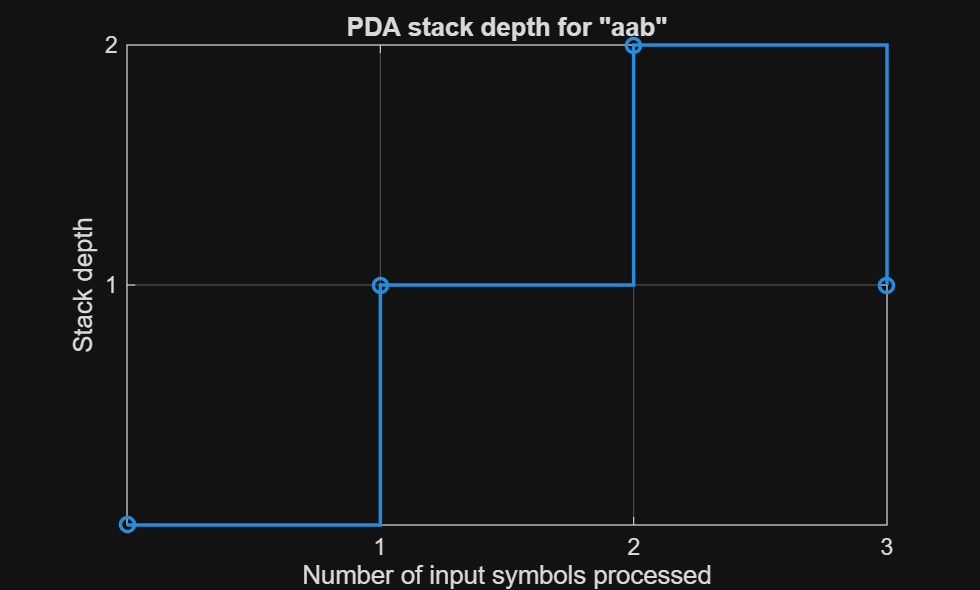

% Uses word input from trace comparisons

% Plot the PDA stack depth
% Depth is the number of 'A' markers currently in the stack

[~, pdaTrace] = simulatePDA(word);

% Reconstruct stack depth from the trace
depth = zeros(1, length(word) + 1);
depth(1) = 0;

for k = 2:length(pdaTrace)
    entry = pdaTrace{k};
    
    if contains(entry, 'push A')
        depth(k) = depth(k-1) + 1;
    elseif contains(entry, 'pop A')
        depth(k) = depth(k-1) - 1;
    else
        depth(k) = depth(k-1);
    end
end

% Only the first length(word) + 1 entries correspond to configurations
depth = depth(1:length(word) + 1);

figure;
stairs(0:length(word), depth, '-o', LineWidth=1.5);
yticks(1:length(word) + 1)
xticks(1:length(word) + 1)
xlabel('Number of input symbols processed');
ylabel('Stack depth');
title(['PDA stack depth for "',word, '"']);
grid on;

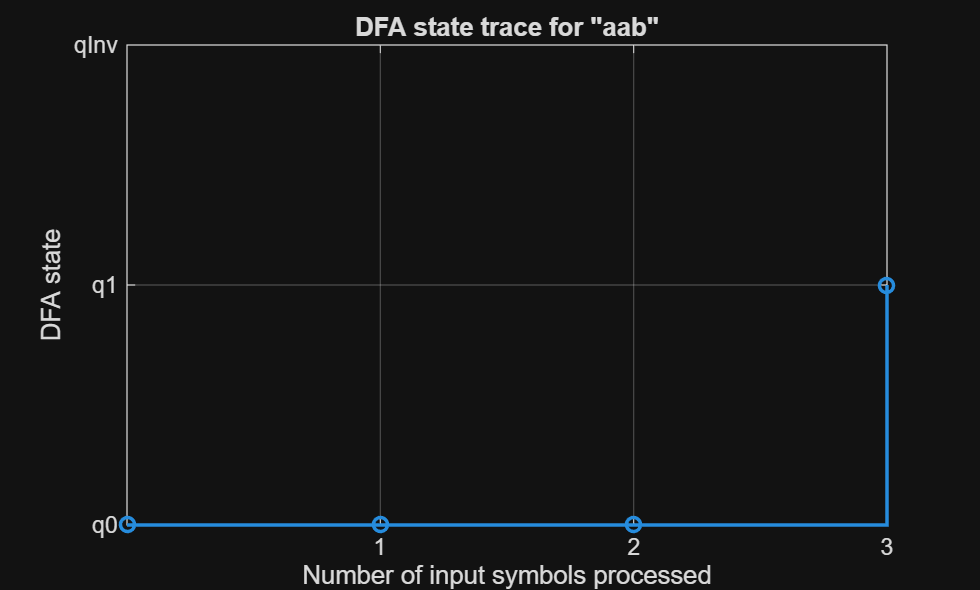



% Plot the DFA trace

[~, dfaTrace] = simulateFA(word);

% Convert state names into numeric values
stateNames = {'q0', 'q1', 'qInv'};
stateValues = zeros(1, numel(dfaTrace));

for k = 1:numel(dfaTrace)
    entry = dfaTrace{k};

    if contains(entry, 'qInv')
        stateValues(k) = 3;
    elseif contains(entry, 'q1')
        stateValues(k) = 2;
    else
        stateValues(k) = 1;
    end
end

figure;
stairs(0:length(word), stateValues, '-o', LineWidth=1.5);
yticks(1:3);
ylim([1 3])
xticks(1:length(word) + 1)
yticklabels(stateNames);
xlabel('Number of input symbols processed');
ylabel('DFA state');
title(['DFA state trace for "', word, '"']);
grid on;